# **Authors**

*The work can be done in groups of up to 3 students. Please complete the following fields with your group number and list your names along with ISU ID numbers.*

**Stream: [RZZZ] Technical Vision**

**Subgroup: **

Student ID 1, Name 1

Student ID 2, Name 2

Student ID 3, Name 3

The task and guidelines were prepared by Andrei Zhdanov and Sergei Shavetov from ITMO University in 2024.

# **Practical Assignment No 6. Images Morphological Analysis**

Studying of the digital images morphological analysis main principles.

## **Task 1. Basic morphological operations**

*Select an arbitrary image containing shape defects (internal "holes" and external  "ledges"). Using basic morphological operations, completely remove or minimize defects.*

### **Introduction**

The term *morphology* literally translates as "the science of form" from Greek. Morphological analysis is used in many areas of knowledge, including image processing. It is a relatively universal approach, therefore it stands apart from all previously considered methods. Using mathematical morphology in image processing, it is possible to filter noise, segment objects, detect edges, implement a search for a given object in an image, calculate the image "skeleton", etc. Let's consider the image binary morphology basic operations $A$ by the structuring element $B$:

 - Dilation: $C = A \oplus B$ dilates binary image $A$ by structuring element $B$;

 - Erosion: $C = A \ominus B$ narrows down the binary image $A$ by structuring element $B$;

 - Open: $C = (A \ominus B) \oplus B$ removes binary image external defects $A$ by structuring element $B$;

 - Close: $C = (A \oplus B) \ominus B$ removes binary image internal defects $A$ by structuring element $B;$

$\oplus$ and $\ominus$ operations which were used above are addition and subtraction of Minkowski, respectively.

One of examples of using the morphological operations is edge detection. Morphological operations allows us calculating the inner and outer shape, dedending on which operation is used:

 - $C=A-(A\ominus B)$ - the inner edge is the difference between the image and its erosion result

 - $C=(A\oplus B)-A$ - the outer edge is the difference between the image dilations and itself.

Now when we learned what the morphological operations are, let's try them in action.

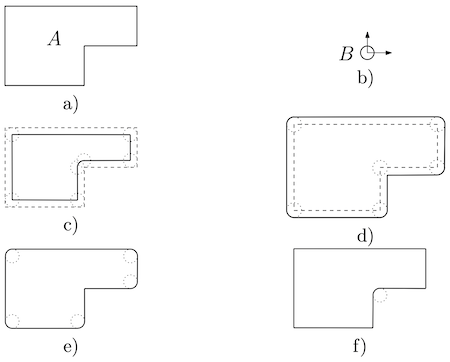

*The result of binary morphological operations: a) binary image *$A$*, b) disk-shape structuring element *$B$*, c) dilation, d) erosion, e) open, f) close.* 

### **Morphological operations with MATLAB**

MATLAB provides following general functions to work with morphological operations:

` - ```imerode()`` `-` perform the morphological erosion operation $C = A \ominus B$.

` - ```imdilate()``` - `perform the morphological dilation operation $C = A \oplus B$.

` - ```imopen()``` - `perform the morphological opening operation $C = (A \ominus B) \oplus B$: $open(A, B) = dilate(erode(A, B), B)$.

` - ```imclose()``` - `perform the morphological closing operation $C = (A \oplus B) \ominus B$: $close(A, B) = erode(dilate(A, B), B)$.

` - ```imtophat()``` - `perform the morphological "top hat" operation. This is the difference between image and its opening: $tophat(A, B) = A - open(A, B)$;

` - ```imbothat()``` - `perform the morphological "bottom hat" operation. This is the difference between image closing and an image: $bottomhat(A, B) = close(A, B)  - A$;

` - ```imclearborder()``` - `Suppress light structures connected to image border.

` - ```imfill()``` - `Fill image regions and holes.

` - ```bwhitmiss()``` - P`erform the opening "hit & miss" operation.

` - ```bwmorph()``` - `Morphological operations on binary images.

` - ```bwmorph3()``` - `Morphological operations on binary volume.

` - ```bwperim()``` - `Find perimeter of objects in binary image.

` - ```bwskel()``` - `Reduce all objects to lines in 2-D binary image or 3-D binary volume.

` - ```bwulterode()``` - `Ultimate erosion. The ultimate erosion of `BW` consists of the regional maxima of the Euclidean distance transform of the complement of `BW`.

There are several more functions which are useful when working with morphology:

` - ```imreconstruct()``` - `Morphological reconstruction.

` - ```imregionalmax()``` - `Regional maxima.

` - ```imregionalmin()``` - `Regional minima.

` - ```imextendedmax()``` - `Extended-maxima transform.

` - ```imextendedmin()``` - `Extended-minima transform.

` - ```imhmax()``` - `H-maxima transform.

` - ```imhmin()``` - `H-minima transform.

` - ```imimposemin()``` - `Impose minima.

There are several functions for creating structuring elements and connectivity arrays:

` - ```strel()``` - `Morphological structuring element.

` - ```offsetstrel()``` - `Morphological offset structuring element.

` - ```conndef()``` - `Create connectivity array.

` - ```iptcheckconn()``` - `Check validity of connectivity argument.

### **1.1 Preparation**

First, we need to clear Command window and Workspace.

clc
clear all

### 1.2 Read and display an image

Now let's open our image which we will use in the current task. Since the image is a binary image, we will convert it in grayscale. The binary image we are going to use is in fact the grayscale image, however it has only two types of pixels: black pixels with values $0$ and white pixels with value 1. White pixels define the shape pixels and black ones are background. Such image can be created from a grayscale image by thresholding it using ``graythresh()`` for global image threshold calculation by Otsu's method  with ``imbinarize()`` function.

% Read a binary image from file and binarize it
I = imread('star.png');
I = rgb2gray(I);
t = graythresh(I);
I1 = ~imbinarize(I,t);
figure
imshow(I1);

### **1.3 Morphological operations**

Before trying to clean up an image, we will try running considered morphological operations on it.

#### **1.3.1 Structuring element**

The first thing we need to to is create a structuring element. Let's create different default types of elements and display them to have a look.

% Create an 11 x 11 pixels cirle structuring element (filled circle)
disk_element = strel('disk',6); % 6 is a radius of structuring element, the size is 11 x 11

% Create an 11 x 11 pixels rectangular structuring element
rect_element = strel('rectangle',[11 11]);

% Create an 11 x 11 pixels diamond shape structuring element
diamond_element = strel('diamond',5);  % 5 is a distance from the structuring element origin to the points of the diamond, the size is 11 x 11

% Displaying structuring elements
figure;

subplot(1,3,1);
imshow(disk_element.Neighborhood);
title('Disk');

subplot(1,3,2);
grid on;
set(subplot(1,3,2),'Color','Black');
imshow(rect_element.Neighborhood);
title('Rect');

subplot(1,3,3);
imshow(diamond_element.Neighborhood);
title('Diamond');

As you see, the structuring element is a binary matrix with `1` meaning that this pixel is used in morphological operations and `0` meaning that pixel is omitted. So, this is very similar to kernels which were used during 2D filters and we can create own elements if needed.

During this assignment we will use the disk structuring element, however you may try using the different one and compare the results.

% Shorten the element name
element = disk_element;

#### **1.3.2 Erode operation**

The first operation we will try is an erode operation. It erodes the binary image narrowing the shape. Let's run it several times and check how it affect the object morphology.

% Try the erode operation
I1erode1 = imerode(I1, element);        % Erode 1 time
I1erode2 = imerode(I1erode1, element);  % Erode 2 times
I1erode3 = imerode(I1erode2, element);  % Erode 3 times

figure;
subplot(1,4,1);
imshow(I1);
title('Source');
subplot(1,4,2);
imshow(I1erode1);
title('Erode 1 iteration');
subplot(1,4,3);
imshow(I1erode2);
title('Erode 2 iterations');
subplot(1,4,4);
imshow(I1erode3);
title('Erode 3 iterations');

As you can see, eroding a morphology decreases it's side and completely removes small external areas, however internal holes got bigger.

#### **1.3.3 Dilation operation**

Opposite to erosion, dilation operation grows and object. Let's run it several times and check how it affect the object morphology.

% Try the dilate operation
I1dilate1 = imdilate(I1, element);         % Dilate 1 time
I1dilate2 = imdilate(I1dilate1, element);  % Dilate 2 times
I1dilate3 = imdilate(I1dilate2, element);  % Dilate 3 times

figure;
subplot(1,4,1);
imshow(I1);
title('Source');
subplot(1,4,2);
imshow(I1dilate1);
title('Dilate 1 iteration');
subplot(1,4,3);
imshow(I1dilate2);
title('Dilate 2 iterations');
subplot(1,4,4);
imshow(I1dilate3);
title('Dilate 3 iterations');

As you can see, now all internal holes are filled, the object increased its size, however all outside noise also got much more noticeable.

#### **1.3.4 Open operation**

The open operation is a dilation of an erosion of the object morphology. It should allow removing the external object morphology defects while keeping the general shape and shape size almost untouched. Let's run it several times and check how it affect the object morphology.

% Try the open operation
I1open1 = imopen(I1, element);       % Open 1 time
I1open2 = imopen(I1open1, element);  % Open 2 times
I1open3 = imopen(I1open2, element);  % Open 3 times

figure;
subplot(1,4,1);
imshow(I1);
title('Source');
subplot(1,4,2);
imshow(I1open1);
title('Open 1 iteration');
subplot(1,4,3);
imshow(I1open2);
title('Open 2 iterations');
subplot(1,4,4);
imshow(I1open3);
title('Open 3 iterations');

You can see that now most of the external defects are removed while internal ones are more or less as they were before.

#### **1.3.5 Close operation**

The close operation is an erosion of a dilation of the object morphology. It should allow removing the internal object morphology defects while keeping the general shape and shape size almost untouched. Let's run it several times and check how it affect the object morphology.

% Try the close operation
I1close1 = imclose(I1, element);        % Close 1 time
I1close2 = imclose(I1close1, element);  % Close 2 times
I1close3 = imclose(I1close2, element);  % Close 3 times

figure;
subplot(1,4,1);
imshow(I1);
title('Source');
subplot(1,4,2);
imshow(I1close1);
title('Close 1 iteration');
subplot(1,4,3);
imshow(I1close2);
title('Close 2 iterations');
subplot(1,4,4);
imshow(I1close3);
title('Close 3 iterations');

You can see that now most of internal defects are removed while the external ones are more or less as they were before.

#### **1.3.6 Contours**

With morphology it's easy to extract the object contours. We can get either internal or external contour of an object:

 - To get an internal contour of an object, we have to subtract the object erosion result from the object itself;

 - To get an external contour of an object, we have to subtract the object from its dilation result.

The width of the contour is defined by the structuring element. To check these methods, we will create a smaller structuring element with size $3 \times 3$.

% Create a 3 x 3 disk structuring element
element3x3 = strel('disk',1); % r = 1, the size is 3x3
I1internal = I1 - imerode(I1, element3x3);
I1external = imdilate(I1, element3x3) - I1;
figure;
subplot(1,3,1);
imshow(I1);
title('Source');
subplot(1,3,2);
imshow(I1internal);
title('Internal contour');
subplot(1,3,3);
imshow(I1external);
title('External contour');

#### **1.3.7 BW Area Open operation in MATLAB**

MATLAB provides a very useful operation named ``bwareaopen()`` which works with morphology. This operation searches for all areas of size less than the given one and opens them. This operation is very handy when working with morphology as it allows to remove all small areas from morphology, so let's implement it. Try running it with our source image and open all areas with size less than 30.

I1bwao = bwareaopen(I1, 30);
figure;
subplot(1,2,1);
imshow(I1);
title('Source');
subplot(1,2,2);
imshow(I1bwao);
title('bwareaopen');

As you see, all external shapes with area size less than $30$ were removed. However we can use this function to remove internal holes too. To do this we have to invert the morphology, call the ``bwreaopen()`` function and invert the result. Let's remove all holes with size less than $25$ from our morphology object.

% Remove all areas with holes size less than 25 
I1ibwao = ~bwareaopen(~I1, 25);
figure;
subplot(1,2,1);
imshow(I1);
title('Source');
subplot(1,2,2);
imshow(I1ibwao);
title('Inverse bwareaopen');

If we want to remove both small external objects and internal holes, then we need to combine these two operations.

% Remove all areas with area size less than 30 and holes with size less than 25 
I1ibwao = ~bwareaopen(~bwareaopen(I1, 30), 25);
figure;
subplot(1,2,1);
imshow(I1);
title('Source');
subplot(1,2,2);
imshow(I1ibwao);
title('Double bwareaopen');

### **1.4 Cleaning up an image**

Now we learned some basic morphological operations and can clean this image. So, what we know now:

1. We can remove all external small areas by using the ``bwareaopen()`` function;

2. We can remove all internal holes by using the inverse of the ``bwareaopen()`` function;

3. We can clean the internal defects by using the $close$ operation;

4. We can clean the external defects by using the $open$ operation.

Let's use these operation parameters and adjust their parameters to clean up our source image. We will use the small structuring element and run several iterations of morphological operations to reduce the affection of the general morphology shape.

% First we use bwareaopen and open all external small areas
I1clean1 = bwareaopen(I1, 20);

% First we need to adjust the structuring element shape and size
I1clean2 = bwmorph(I1clean1,'erode',3);
I1clean3 = bwmorph(I1clean2,'dilate',7);
I1clean4 = bwmorph(I1clean3,'erode',4);

% Find a contour with 3 pixels contour
I1clean5 = I1clean4 - bwmorph(I1clean4,'erode',3);

figure
subplot(2,3,1);
imshow(I1);
title('Source');
subplot(2,3,2);
imshow(I1clean1);
title('Eliminate 20 px areas');
subplot(2,3,3);
imshow(I1clean2);
title('Applied 3 erosions');
subplot(2,3,4);
imshow(I1clean3);
title('Applied 7 dilations');
subplot(2,3,5);
imshow(I1clean4);
title('Applied 4 erosions');
subplot(2,3,6);
imshow(I1clean5);
title('Calculated contour');

# ***Self-work***

**Select an arbitrary image containing shape defects (internal "holes" and external "ledges"). Use the basic morphological operations to completely remove or minimize these defects.**

% TODO Place your solution here
%I2own = ;






## **Task 2. Objects splitting**

*Select an arbitrary binary image containing overlapping objects. Use binary morphology operations to separate objects.*

### **2.1 Example**

One of the examples of using morphological operations on an image is the problem of on an image separating objects glued together. The problem can be solved with a sufficient degree of accuracy by sequentially executing the erosion filter several times, and then dilate the result. Intersection of the original image with the processed one will separate the glued objects.

Let's try implementing this algorithm.

#### **2.1.1 Read and preprocess an image**

First of all we need some input image. It's not so interesting to start working with morphology directly, so we will take some image with objects, threshold it to get a binary image, clean it up and use this cleaned up morphology as a starting point. For this we will use an image with some coins on a white table. 

Now we have get a morphology from it. For this we will first convert it to grayscale and threshold the grayscale image.

% Read a binary image from file and display it
I = imread('coins.jpg');
figure
I2gray = im2gray(I);
t = graythresh(I2gray);
I2bw = ~imbinarize(I2gray,t);
montage({I, I2gray, I2bw});

#### **2.1.2 Clean up the image**

Now we got a morphology we can work with. Let's clean it, we know how to do it already. Most of defects can be cleaned by inverse bwareaopen operations. Other can be cleaned by applying the closing operation.

% Fill holes
I2clean1 = ~bwareaopen(~I2bw, 150);

% Create structuring element
element3x3 = strel('disk',1);

% Close several times to finish cleaning
I2clean2 = imclose(I2clean1, element3x3);
montage({I2clean1, I2clean2});

I2clean = I2clean2;

#### **2.1.3 Split objects with erosion**

Now we got a clean morphology, but it still has several objects glued together, so we have to separate them. Let's erode it several times with $7 \times 7$ element. This will give us small separate objects in the centers of objects we are searching for. If we invert the result we will get a shape of the border between objects.

% Create structuring element
element7x7 = strel('disk', 4); % r = 4, size = 7 x 7
for i=1:8
    I2clean = imerode(I2clean,element7x7);
end
I2centers = I2clean;
I2border = ~I2centers;
figure
subplot(1,2,1);
imshow(I2centers);
title('Erode 8 iterations');
subplot(1,2,2);
imshow(I2border);
title('Border');

#### **2.1.4 Find borders**

As you see, we can't use these borders directly, we have to thicken them. For this need we will use the following algorithm:

 1. Erode the image;

 2. Open the erosion result;

 3. Subtract the erosion result from opening of the erosion;

 4. Add the subtraction result to a thickened borders accumulated;

 5. If there are still any non-zero pixels in the image *go to sep 1*.

The main idea of this algorithm is that after each erosion we check if the line disappeared in some point by comparing it with opening result. If yes, then we add these pixels to the thickened border. We can adjust this algorithm by using different structuring elements at erosion and opening operations.

element3x3 = strel('rectangle',[3 3]);
element7x7 = strel('disk',4);
I2tmp = I2border;
I2border2 = zeros(size(I2tmp));
while nnz(I2tmp) > 0
    % Dilate
    I2tmp_erode = imerode(I2tmp, element3x3);
  
    % Closing on dilated image
    I2tmp_open = imopen(I2tmp_erode, element7x7);
  
    % Subtract them as masks
    subset = I2tmp_erode & ~I2tmp_open;

    % Unite subtraction results with all previous sets
    I2border2 = I2border2 | subset;
  
    % Continue working with dilated image at next iteration
    I2tmp = I2tmp_erode;
end
figure;
subplot(1,2,1);
imshow(I2border);
title('Thick border');
subplot(1,2,2);
imshow(I2border2);
title('Thin border');

#### **2.1.5 Process the result**

Now we have thin borders and we can subtract these borders from out morphology and split objects.

I2m_split = ~I2border2 & I2clean2;
figure;
imshow(I2m_split);
title('Result');

Now let's display obtained results.

figure;
subplot(1,3,1);
imshow(I);
title('Source');
subplot(1,3,2);
imshow(I2bw);
title('Binarized image');
subplot(1,3,3);
imshow(I2m_split);

As you can see this method result is not perfect, so we will use another one to get better object separation results.

# ***Self-work***

**Select an arbitrary binary image containing overlapping objects. Use binary morphology operations to separate objects.**

**You may start with object morphology image and do steps 2.1.3 - 2.1.5 only.**

***Optional: start with objects image and do all steps.***

% TODO Place your solution here
% I2own = None





## **Task 3. Morphological watershed segmentation**

*Select an arbitrary image containing a small number of local minima. Perform image segmentation by watershed approach.*

Let us consider one more example of the mathematical morphology application to the image segmentation problem. In the watershed segmentation approach, an image is viewed as a height map, in which pixel intensities describe heights relative to a certain level. On such a "altitude area" is "pouring rain", forming a multitude of *drainage basins*. Water in overflowing basins merge basins into larger ones (see the figure below).

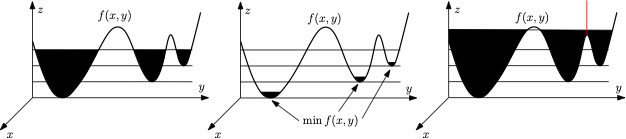

*Watershed areas.*

Basin junctions are marked as watershed lines. If the "rain" is stopped early, then the image will be segmented into small areas, and if it is late then into large ones. In this approach, all pixels are divided into three types:

 - *local minima*;

 - *on the slope* (from which the water rolls down to the same local minimum);

 - *local maxima* (from which the water rolls down to more than one minimum).

When implementing this method, it is necessary to determine the catchment basins and watershed lines by processing local areas and calculating their characteristics. The segmentation algorithm consists of the following steps:

 1. Segmentation function calculation. Typically, a image gradient representation is used for this.

 2. Foreground markers calculation. Typically, it is based on the pixel connectivity of each object.

 3. Background marker calculation. This marker represents non-object pixels.

 4. Segmentation function execution, taking into account the relative position of the foreground and background markers.

As a algorithm result, a mask will be obtained, where the same segments pixels will be marked with the same markers and will form connected areas.

### **3.1 Example**

Let's implement this algorithm step by step.

#### **3.1.1 Read and preprocess an image**

We already know how to do it, so let's read an image.

rgb = imread('oranges.jpg');
figure
imshow(rgb);
title('source image');

Convert it to grayscale.

A = rgb2gray(rgb);
figure
imshow(A);
title('grayscale representation');

#### **3.1.2 Clean up the morphology**

Now we have to clean this morphology a little to detect object centers, using special morphology functions ``imreconstruct()`` and ``imcomplement()``.

B = strel('disk',6);
C = imerode(A,B);
Cr = imreconstruct(C,A);
Crd = imdilate(Cr,B);
Crdr = imreconstruct(imcomplement(Crd), imcomplement(Cr));
Crdr = imcomplement(Crdr);
figure;
imshow(Crdr);
title('filtered image');

#### **3.1.3 Getting foreground markers**

To find area with foreground markers we can use MATLAB ``imregionalmax()`` function that returns the binary image which identifies the regional maxima in grayscale image. Regional maxima are connected components of pixels with a constant intensity value, surrounded by pixels with a lower value.

fgm = imregionalmax(Crdr);
figure;
imshow(fgm);
title('calculated fgm');

Let's apply calculated foreground markers on the grayscale representation.

A2 = A;
A2(fgm) = 255;
figure;
imshow(A2);
title('applied fgm');

`Now, we may perform filtering foreground markers using morphological filters.`

B2 = strel(ones(5,5));
fgm = imclose(fgm,B2);
fgm = imerode(fgm,B2);
fgm = bwareaopen(fgm,20);
A3 = A;
A3(fgm) = 255;
figure;
imshow(A3);
title('filtered fgm');

In the next step we need to obtained binarized grayscale image.

bw = imbinarize(Crdr);
figure;
imshow(bw);
title('binarized image');

#### **3.1.4 Getting background marker**

Next, we have to find a background area marker. It can be found by executing the watershed algorithm on the foreground markers data and selecting the resulting areas boundary area as a background area. This solution works well if objects are placed tightly and background area is hard to mark.

D = bwdist(bw);
L = watershed(D);
bgm = L == 0;
figure;
imshow(bgm);
title('calculated bgm');

#### **3.1.5 Define the watershed parameters**

Now we have information about foreground and background markers positions using Sobel operator and MATLAB function ``imimposemin()` `that modifies the grayscale mask image using morphological reconstruction so it only has regional minima wherever binary marker image is nonzero.

hy = fspecial('sobel');
hx = hy';
Ay = imfilter(double(A), hy, 'replicate');
Ax = imfilter(double(A), hx, 'replicate');
grad = sqrt(Ax.^2 + Ay.^2);
grad = imimposemin(grad, bgm | fgm);
figure;
imshow(grad);
title('gradient segmentation');

#### **3.1.6 Run watershed algorithm and process the results**

Let's display the result using MATLAB function ``watershed()``.

L = watershed(grad);
figure;
imshow(L);
title('segmented gradient');                      

In the next step we may find the borders and display it.

A4 = A;
A4(imdilate(L == 0, ones(3,3)) | bgm | fgm) = 255;
figure;
imshow(A4);
title('segmented image');       

As you see, due to a very thin border, the segmentation result is not perfect and border got significantly thicker due to specifics of the algorithm used.

Let's display our results as different color objects.

Lrgb = label2rgb(L, 'jet', 'w', 'shuffle');
figure;
imshow(Lrgb);
title('RGB-representation');

### **3.2 Another approach for background marker**

Another approach to find a background area marker can be by sequential dilation of the filtered black and white image. The inversion of dilation result should give us an area that is sure to be a background and can act as a background marker. This solution works well in case if background area is rather big and would not become empty after dilation operation.

Let's try this approach on the coins images we saw in the **Task 2** and stored in ``I2`` image with morphology in ``I2clean``.

#### **Foreground markers**

We will repeat same steps to get foreground markers. Let's calculate the distance and the threshold:

% Foreground markers
I2dist = bwdist(~I2clean, 'euclidean'); 
I2dist_norm = I2dist / max(I2dist(:)); % distance normalization
I2fg = I2dist > 0.3 * max(I2dist(:));  % foreground threshold

figure;
subplot(1,2,1);
imshow(I2dist_norm);
title('Distance');
subplot(1,2,2);
imshow(I2fg);
title('Foreground');

In the next step let's calculate foreground markers.

[L, n_markers] = bwlabel(I2fg); % Searching for foreground markers
I2markers_fg = L;  % Foreground markers

% Показ маркеров переднего плана с применением цветовой карты
figure;
subplot(1, 2, 1);
imshow(I2fg);
title('Foreground');

subplot(1, 2, 2);
imshow(label2rgb(I2markers_fg, 'jet', 'k'));
title('Foreground markers');

#### **Background marker**

Background area can be defined by inverse of dilation of the initial morphology.

element49x49 = strel('disk', 25);
I2markers_bg = imdilate(I2clean, element49x49);
I2markers_bg = ~I2markers_bg;

figure;
subplot(1,2,1);
imshow(I2fg);
title('Foreground');
subplot(1,2,2);
imshow(I2markers_bg);
title('Background');

#### **Define parameters**

I2und = ~(I2markers_bg | I2markers_fg);
I2markers = I2markers_fg;
I2markers(I2markers_bg) = n_markers + 1;

figure;
subplot(1,2,1);
imshow(I2und);
title('Undefined');
subplot(1,2,2);
imshow(label2rgb(I2markers, 'jet', 'k'));
title('All markers');

# ***Self-work***

**Select an arbitrary image containing a small number of local minima. Perform image segmentation by watershed approach.**

% TODO Place your solution here
%I3own = None





# ***Self-work***

**Answer questions and conclude your work results.**

## **Questions **

Please answer the following questions:

 -  Does the opening result include the closing result?

** > Put your answer here**

 - What morphological filter should be applied to remove ledges from an object?

** > Put your answer here**

 - How can you find the object edges using morphological operations?

** > Put your answer here**

 - What is morphology?

** > Put your answer here**

## **Conclusion**

What have you learned with this task? Don't forget to conclude it.

 **> Put your answer here**